# Two-link planar Joint Control

## Objective:

 Implement joint controllers for a two-link planar using different approaches in ideal and realistic cases (where sensor and parameter variations are considered).

## **prerequisite:**

- Completed the dynamics formulation and simulation `1_twolink_planar_dynamics.mlx (``in` ../2-dynamics directory) and copied *gen_twolink_ss*.*m* script to this folder.

- Understands the theory behind different Control strategies

- Reference reading: Chapter 8 of Robotics Modelling, Planning and Control  by Bruno Siciliano, Lorenzo Sciavicco, Luigi Villani, and Giuseppe Oriolo  

clc;
clear;

## background:

### Control schemes

- ***Decentralized control *****scheme:** Each manipulator joint is controlled independently 

- ***Centralized control *****schemes: **the dynamic interaction effects between the joints are taken into account. 

### ***J******oint space control ***

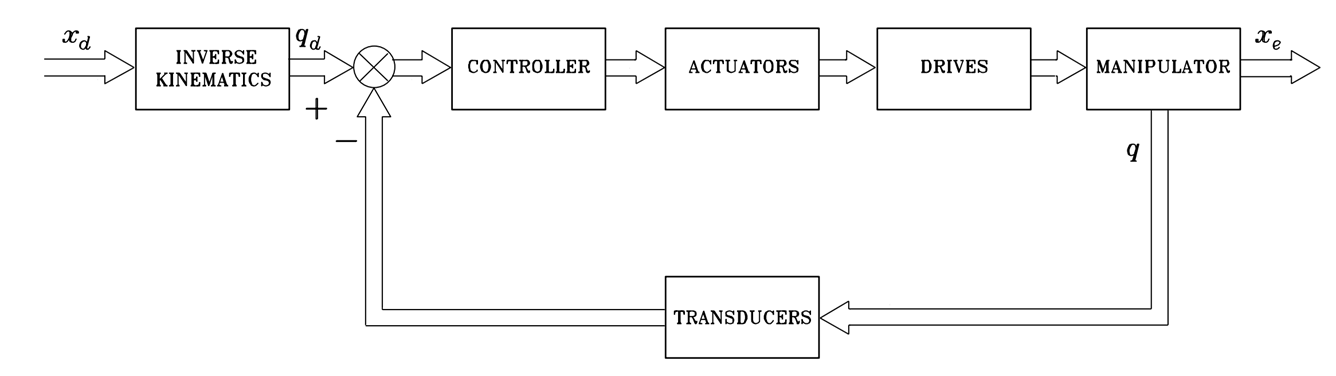

### ***Task space control***

- Either convert to a joint-space trajectory and proceed with controls in Joint Space (above)

- Or express the robot dynamics and control law in the task space

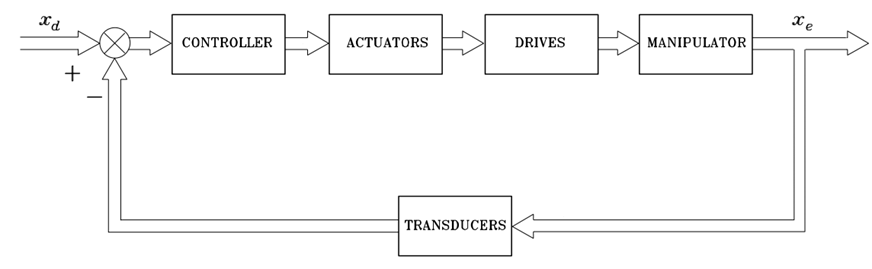

## PD Joint control (Decentralized)

- A PD controller for each joint

- coupling terms are assumed to be disturbance

- A steady state error is present

- Asymptotically stable assuming positive controller gains

- Performance degrades when tracking reference trajectories at high speed and acceleration

#### 
$$\tau =K_p q_e +K_d \dot{q_e }$$


### Tuning controllers (Initial tuning)

- Run the system with zero input torques (gravity collapse) and note the frequency of oscillation $T$(seconds from first peak to second one). This value maybe different for each joint.

- Pick a natual frequency (start from $\frac{2\pi }{T}$ and increment gradually)

- The natural frequency $\omega_n =\frac{2\pi }{T_n }\;$

- Select damping ratio $\zeta$greater than 0: the higher the more damping. Default to 1 (critically damped)

- For PD control (expect a stead state error if no gravity compensation): $K_p =\omega_n^2$ , $K_d =2\zeta \omega_n$ .

## PID Joint control (Decentralized)

- A  PID controller for each joint

- coupling terms are assumed to be disturbance

- Zero steady state error is present

- Asymptotically stable assuming positive controller gains and limited integral gain. It goes unstable if integral gain is very large.

- Performance degrades when tracking reference trajectories at high speed and acceleration

#### 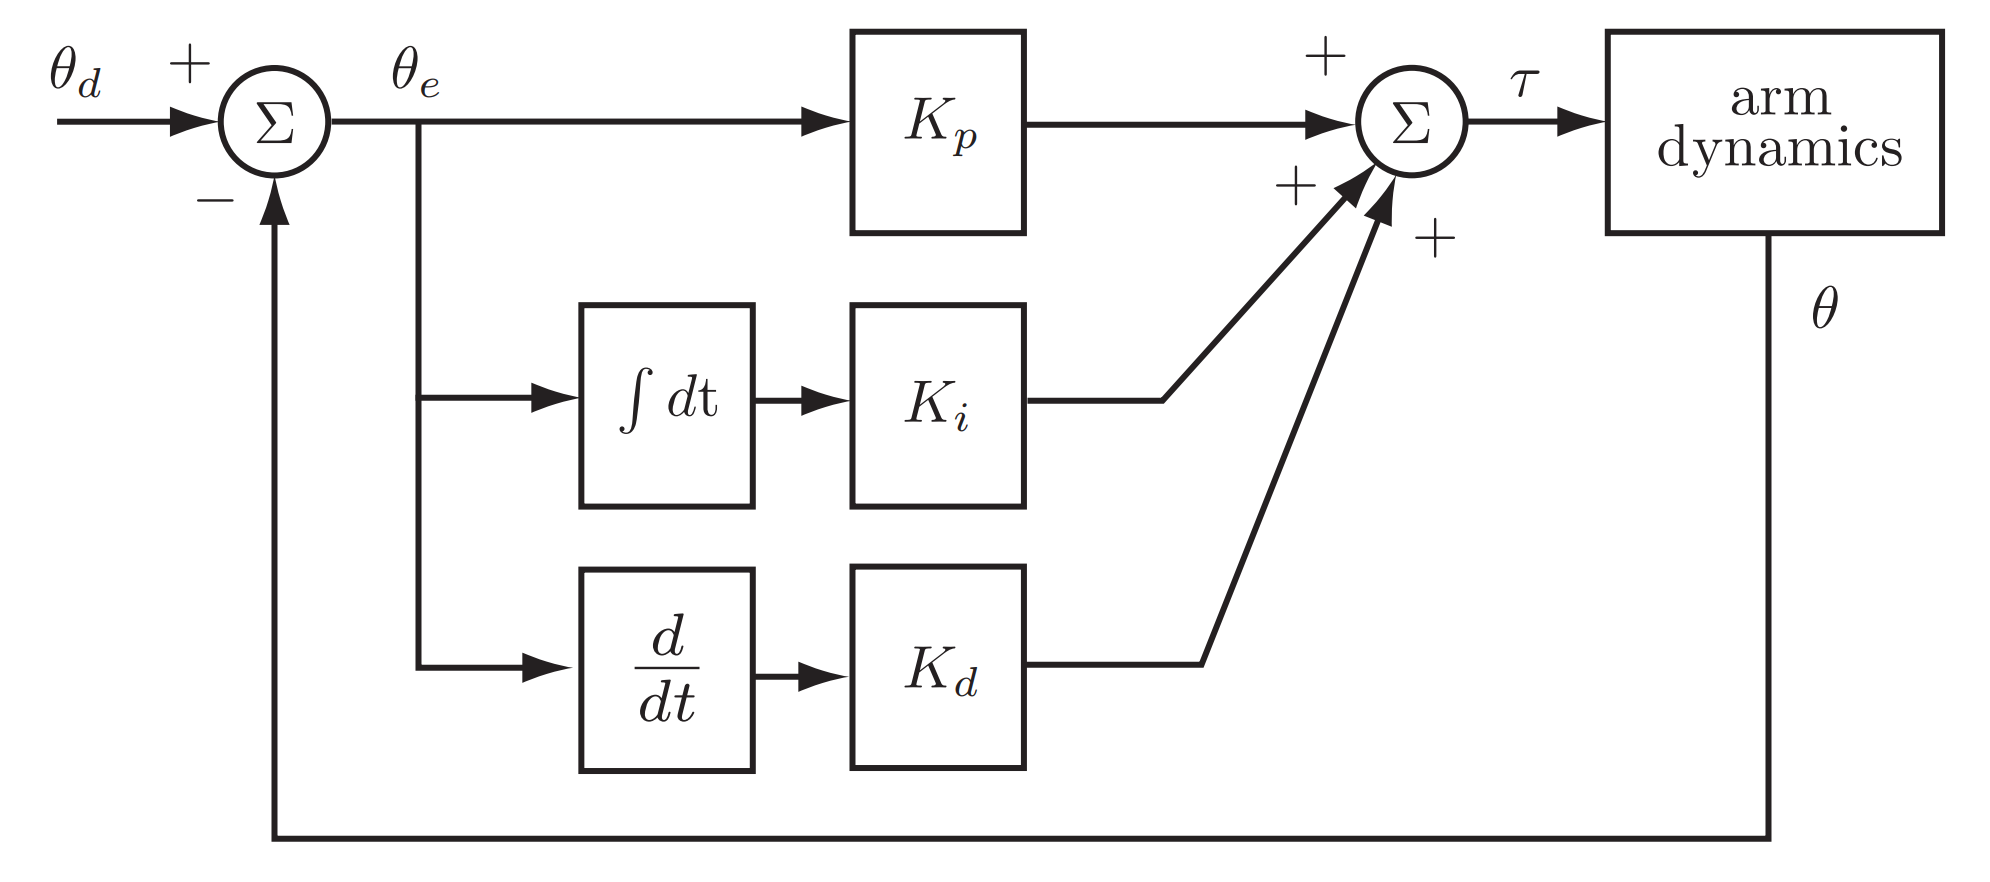

#### 
$$\tau =K_p q_e +K_{i\;} \int q_e \;\textrm{dt}+K_d \dot{q_e }$$


### Tuning controllers (Initial tuning)

- Start with similar values as PD controller and I gain = D gain.

## Full state feedback control  (Decentralized)

- Linearize the system by considering the constant diagonal inertia terms only


$$M\left(q\right)=\bar{M} +\Delta M\left(q\right)$$
 


$$\bar{M} \ddot{\;q} +\textrm{Fv}\dot{\;q} =u$$


- Remaining terms are considered disturbance


$$d=\bar{\Delta M\left(q\right)} \ddot{\;q} +C\left(q,\dot{\;q} \right)\dot{\;q} +g\left(q\right)$$


- Convert to state space and synthesize a control law $\mathit{\mathbf{u}}=\mathit{\mathbf{K}}\left({\mathit{\mathbf{q}}}_{\mathit{\mathbf{d}}} -\mathit{\mathbf{q}}\right)$

state vector: $x=\left\lbrack \begin{array}{c}
\mathit{\mathbf{q}}\\
\dot{\;\mathit{\mathbf{q}}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
q_1 \\
q_2 \\
\dot{\;q_1 } \\
\dot{\;q_2 } 
\end{array}\right\rbrack$


$$\begin{array}{l}
\dot{\mathit{\mathbf{x}}} =\textrm{Ax}+\textrm{Bu}\\
\mathit{\mathbf{y}}=\textrm{Cx}+\textrm{Du}
\end{array}$$


- There are multiple implementation strategies: Scaled reference, state error, and integral action. State error strategy where the gain is multiplied by state error  is shown below

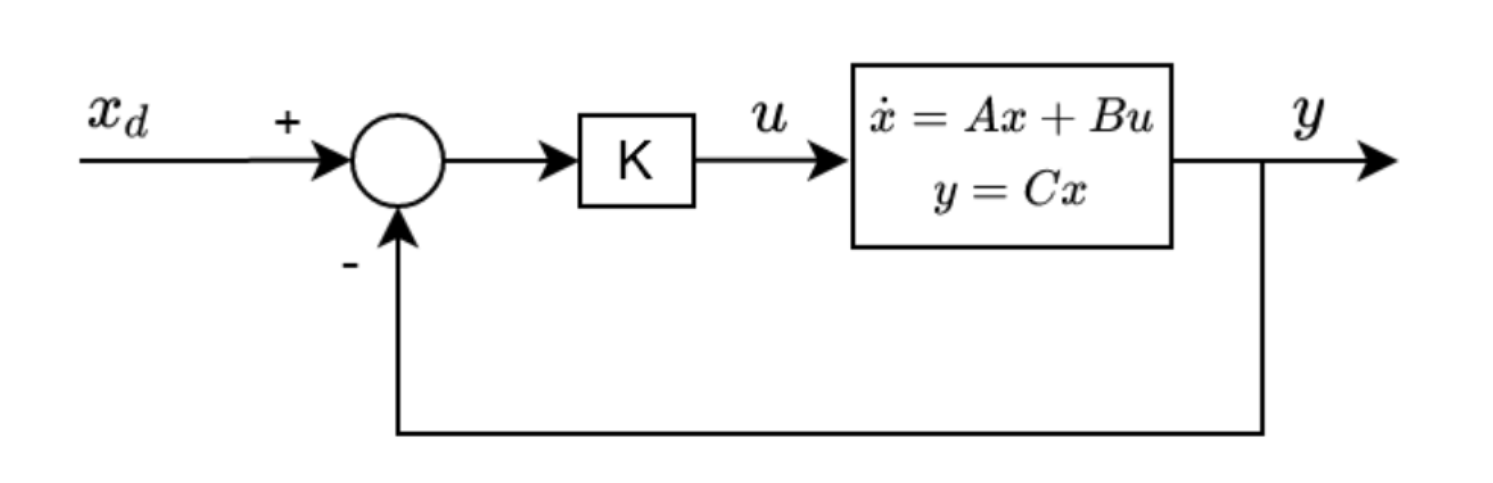

- Disturbance rejection can be improved by adding the disturbance terms to the control law $\mathit{\mathbf{u}}=\mathit{\mathbf{K}}\left({\mathit{\mathbf{q}}}_{\mathit{\mathbf{d}}} -\mathit{\mathbf{q}}\right)+\mathit{\mathbf{d}}$

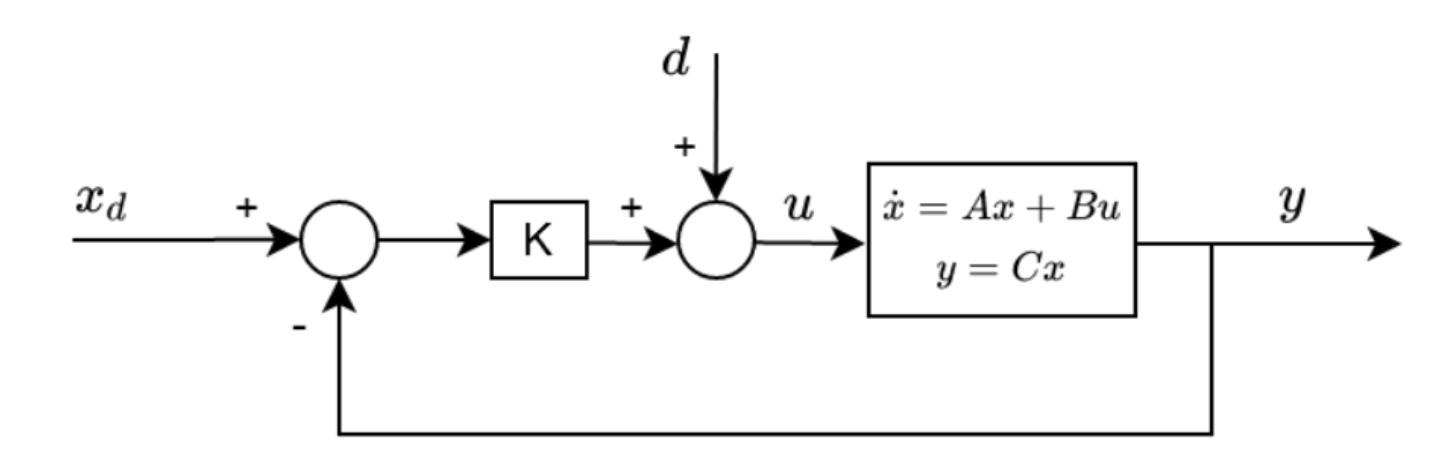

### Finding the gain K

There are multiple ways to find the gain matrix K as follows:

#### Pole Placement method:

- Desired poles of the system are used to calculate the gain matrix K

- The command *K=place(A,B,p);*in Matlab returns the gain matrix K for the provided poles *p.*

- *Finding the desired poles is quite challanging and requires trail and error*

#### Linear Quadratic Regulator (LQR):

- LQR formulates an optimization cost function that is minimized to find the optimal gain matrix K with minimum cost. 

- The cost function is composed of weighted sum of performance and actuator effort over time. 


$$\int_0^{\infty } \left(x^T \textrm{Qx}+u^T \textrm{Ru}\right)\textrm{dt}\;$$


Q is the matrix to panelize bad performance. It is positive definite matrix and is typically diagonal.

R is the matrix to panelize actuator effort. It is positive definite matrix and is typically diagonal.

- Algebraic Riccati equation is solved to get the optimal gain K.

- The command *K=lqr(A,B,Q,R);*in Matlab solves the optimization and returns the optimal gain matrix K.

## Sliding Mode control

- There are many ways to add robustness to the controller, one way is to add sliding mode terms.

- There are many variants of sliding mode control, however we will focus on a basic form here that is model-free.

- The sliding surface is chosen as $S=\lambda \;e\left(t\right)+\dot{\;e} \left(t\right)$ where $e\;\textrm{and}\;\dot{\;e}$ are the error and derivative of error

- A simple control form is to add the sliding control term $K_{\textrm{sm}} \textrm{sig}\left(S\right)$ to an existing control law. For example, modifying LQR+disturbance control law to 


$$\mathit{\mathbf{u}}=\mathit{\mathbf{K}}\left({\mathit{\mathbf{q}}}_{\mathit{\mathbf{d}}} -\mathit{\mathbf{q}}\right)+\mathit{\mathbf{d}}+K_{\textrm{sm}} \textrm{sig}\left(S\right)$$


- To reduce chattering, we can smooth the discontinuity with a saturation layer as follows:

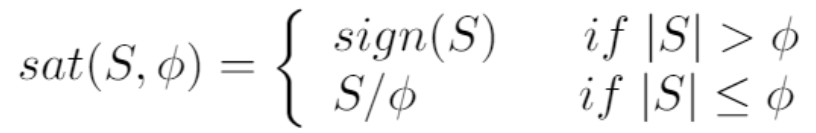

## PD+Gravity compensation Joint control  (Centralized)

- Takes into account the gravity terms

- It is computationally more expensive than PID only control but it is still cheaper than full inverse dynamics control (Next)

- It is good when we don't have a good model of the full dynamics, or the equations may be too computationally expensive to calculate at servo rate. 

- It performs well when the desired velocities and accelerations are small, an approximation

- PD controller can also be replaced by PID controller

- Performance can be improved if friction effects are also added

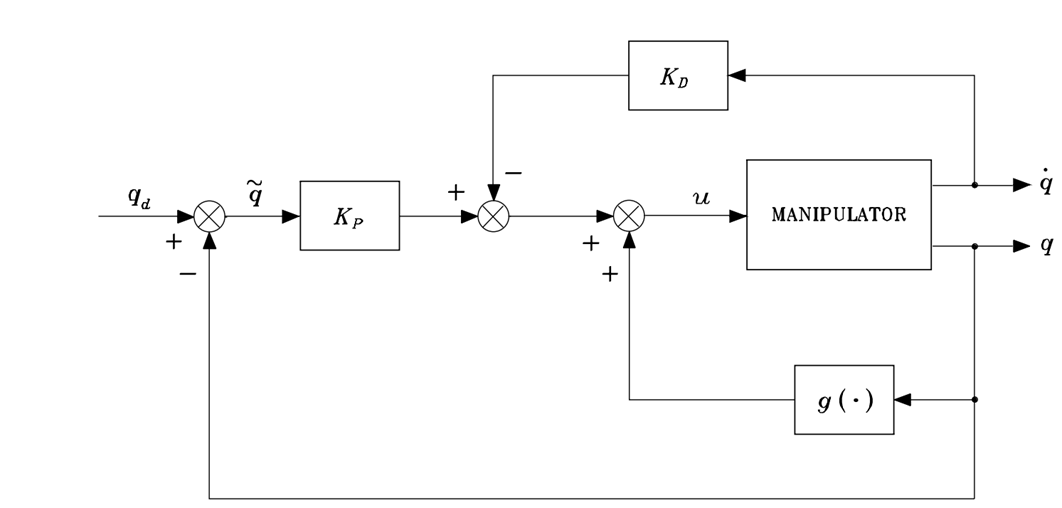

#### 
$$\tau =K_p q_e +K_{i\;} \int q_e \;\textrm{dt}+K_d \dot{q_e } +\tilde{g} \left(q\right)$$


## Inverse dynamics control (Centralized)

- Also called **Computed Torque Feedforward Control**

- Very sensitive to dynamics modelling.

- Feedback linearization + linear controller (PD or PID)

### 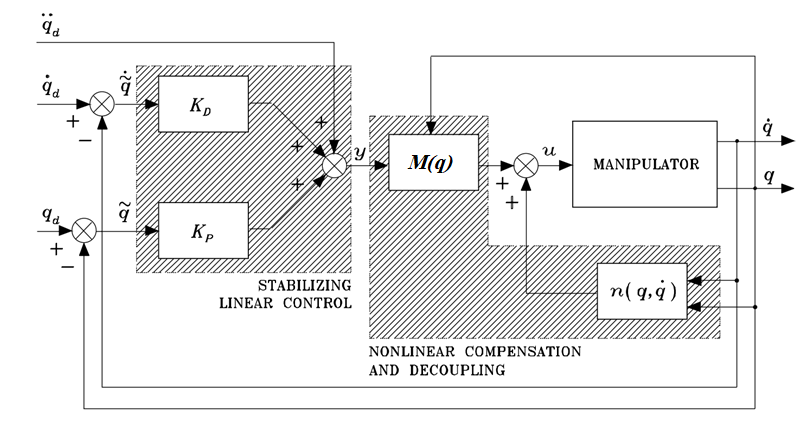

#### 
$$\tau =\tilde{M} \left(q\right)\left(\ddot{q_d } +K_p q_e +K_{i\;} \int q_e \;\textrm{dt}+K_d \dot{q_e } \right)+\tilde{n} \left(q,\dot{\;q\;} \right)$$


## Robust control (Centralized)

- Extends inverse dynamics control to deal with imperfect model compensation and intentional simplification in inverse dynamics computation

### 
$$\tau =\tilde{M} \left(q\right)\left(\ddot{q_d } +K_p q_e +K_{i\;} \int q_e \;\textrm{dt}+K_d \dot{q_e } +\omega \;\;\right)+\tilde{n} \left(q,\dot{\;q\;} \right)$$


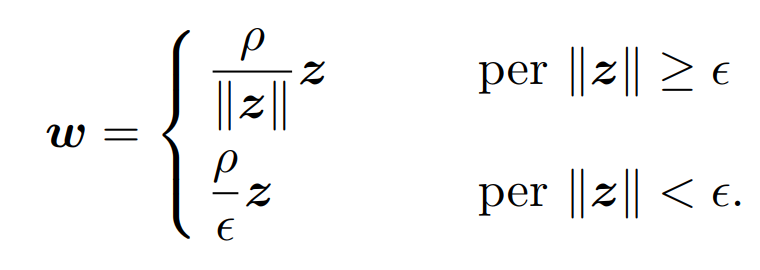

### 
$$z=D^T Q\left\lbrack \begin{array}{c}
\tilde{\;q} \\
\tilde{\;\dot{\;q} } 
\end{array}\right\rbrack$$
 
$$,\;D={\left\lbrack \begin{array}{c}
O\\
I
\end{array}\right\rbrack }_{2n\times n}$$


- Requires solving the Lyapunov equation below to get **Q**

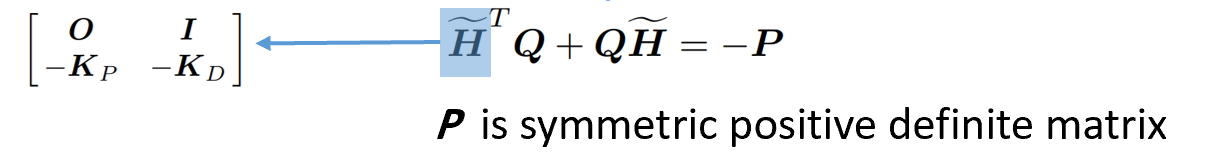

- $\rho ,\sigma \;$ and **P** are free parameters. e.g. $\sigma =1,\rho =0\ldotp 01,\mathit{\mathbf{P}}=\mathit{\mathbf{I}}$

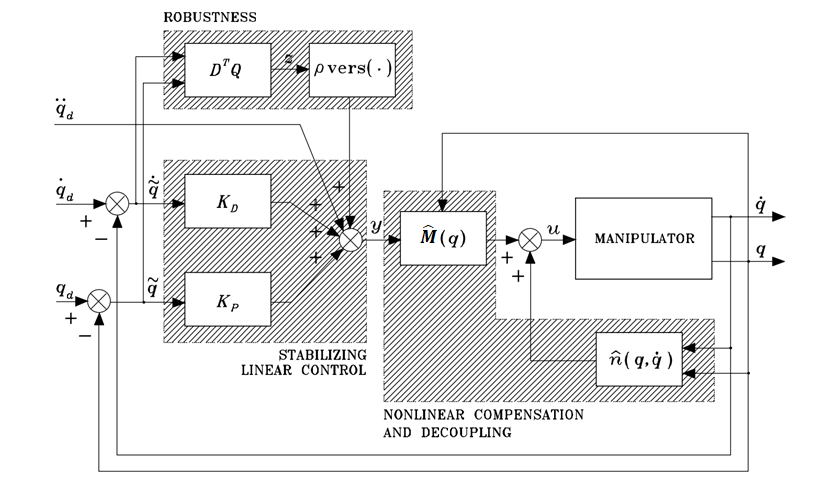

Additional references to understand sliding mode control:

- [https://www.youtube.com/watch?v=1Nji_sJkLvw](https://www.youtube.com/watch?v=1Nji_sJkLvw)

## Running the simulations

Multiple controllers are simulated as variant subsystems. i.e. you can select which controller to run in each simulation. This also goes for robot model and trajectory commands.

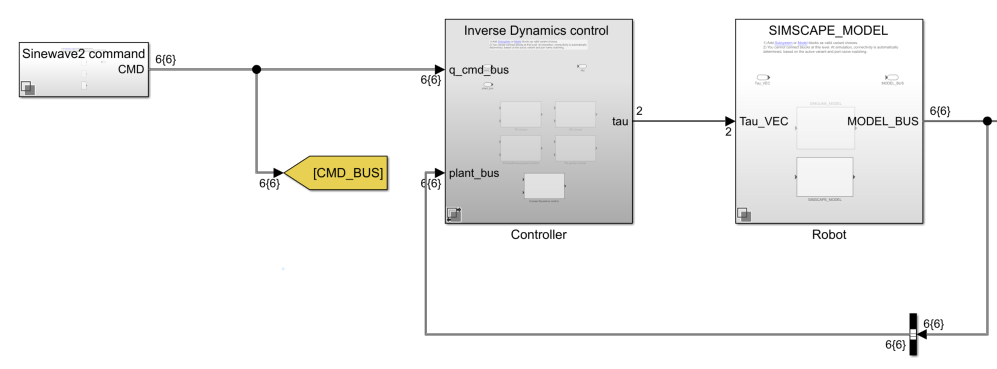

To select a variant controller/trajectory, right-click on the block lower left corner and select the desired variant label.

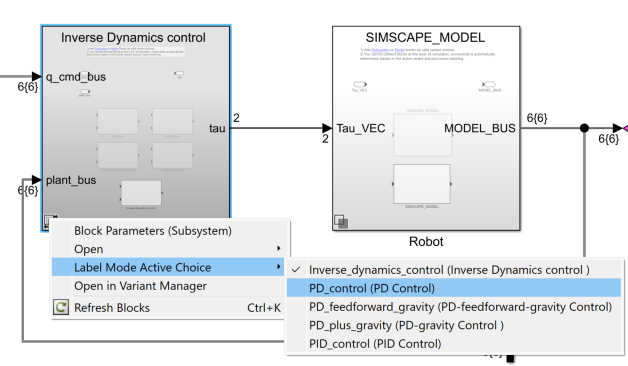

### Import robot parameters

run('sim_params.m');

### Tuning parameters

T = 1.2; %seconds
Tn = T; % T/2.3
damp_ratio = 1;
wn = 2*pi/Tn

wn = 5.2360

### Ideal Simulation

Exact dynamic parameters used in the contollers

% no deviations in parameters (Exact parameters used in controllers)
vis_dev    = 1;
length_dev = 1;
m_dev      = 1;

### PID gains for PD/PID controllers

Kp1 = 30;
Ki1 = 20;
Kd1 = 2.5;
N1 = 100;

Kp2 = 7;
Ki2 = 15;
Kd2 = 0.5;
N2 = 100;

## Poles and gain for Pole Placement control

% ensure sim_params.m has been ran first
sys = ss(A,B,C,D);
% current system poles
% p =  eig(sys)';
% p = [-140, -150, -140.6, -10];
p = [-90, -80, -70, -10.8];
Kpp = place(A,B,p)

Kpp =   163.6799         0   17.4838         0
         0   77.0063         0    1.8082


A_cl = A-B*Kpp;
eig(A_cl)

ans =   -10.8000
  -70.0000
  -80.0000
  -90.0000


syscl = ss(A_cl,B,C,D);
% try to find scaling gain (scaled reference strategy)
Kdc = dcgain(syscl);
Kr = 1./Kdc;
Kr(isinf(Kr))=0

Kr =   163.6799         0
         0   77.0063
         0         0
         0         0


## Gain for LQR control

% ensure sim_params.m has been ran first
sys = ss(A,B,C,D);
% Q and R for cost function
Q = diag([100,50,1,1]);
R = diag([0.1,0.1]);
Klqr = lqr(A,B,Q,R); 
A_cl = A-B*Klqr;
eig(A_cl);
syscl = ss(A_cl,B,C,D);
Kdc = round(dcgain(syscl),2);
Kr_lqr = 1./Kdc; % scaling terms to eliminate sse
Kr_lqr(isinf(Kr_lqr))=0

Kr_lqr =    33.3333         0
         0   25.0000
         0         0
         0         0


### Sliding mode control (Robust)

phi = [0.1;0.1]; % boundray layer
lambda = [5;5]; % surface gain (bandwidth layer lambda)
Kslide = [10;10]; % sliding mode gain [7;0.2]


### Calculate PD gains for PD with gravity compensation 

Kp1_grav  = 15;
Kd1_grav  = 2.5;
N1_grav  = 100;

Kp2_grav  = 3.5;
Kd2_grav  = 0.5;
N2_grav  = 100;

### Calculate PD gains for inverse dynamics control

Kp1_inv  = 25;
Kd1_inv  = 12;
N1_inv  = 50;

Kp2_inv  = 50;
Kd2_inv  = 15;%48
N2_inv  = 50; 

### Robust Control parameters

n = 2;
P = eye(2*n)/10^10;
epsilon = 0.1; % 0.01
rho = [1;1];
D = [zeros(n); eye(n)];

Kp1_robust  = 25;
Kd1_robust  = 7;
N1_robust   = 50;

Kp2_robust   = 45;
Kd2_robust   = 35;
N2_robust   = 50;

Kp_r = eye(n).*[Kp1_robust ;Kp2_robust ];
Kd_r = eye(n).*[Kd1_robust ;Kd2_robust ];
telda_H = [zeros(n)   ones(n);
              -Kp_r     -Kd_r;] % telda_H must have eigenvalues with negative real parts

telda_H =      0     0     1     1
     0     0     1     1
   -25     0    -7     0
     0   -45     0   -35


Q =  lyap(telda_H,P)

Q = 	1.0e+04 *

    0.3146   -0.8738   -1.1235    1.1235
   -0.8738    2.4273    3.1208   -3.1208
   -1.1235    3.1208    4.0124   -4.0124
    1.1235   -3.1208   -4.0124    4.0124


D_T_Q = D'*Q;

Open simulation

open_system("sim_1_twolink_joint_control_ideal.slx")

### Realistic simulation

This model adds:

- Gaussian measurement noise (Position only)

- Measurement low-pass filter (position, velocity and acceleration)

- Torque limits

- Dynamic parameter variations ( those used in the controller block for example to calculate gravity compensation)

Add dynamic parameter variations (mass, link length, viscous coefficient)

% percent deviation for all static parameters 
param_dev = 15; % within 15%
rng(1000) %fix random seed
length_dev = (100+randi([-param_dev,param_dev],1))/100.0;
vis_dev = (100+randi([-param_dev,param_dev],1))/100.0;
m_dev = (100+randi([-param_dev,param_dev],1))/100.0;
vis_dev,length_dev,m_dev

vis_dev = 0.8800

length_dev = 1.0500

m_dev = 1.1400

### PID gains for PD/PID controllers

Kp1 = 30;
Ki1 = 20;
Kd1 = 2.5;
N1 = 100;

Kp2 = 7;
Ki2 = 15;
Kd2 = 0.5;
N2 = 100;

## Poles and gain for Pole Placement control

% ensure sim_params.m has been ran first
sys = ss(A,B,C,D);
% current system poles
% p =  eig(sys)';
% p = [-9, -8, -7, -1.8];
p = [-25, -24, -23, -5.8];
Kpp = place(A,B,p) % feedback gain

Kpp =    28.8821         0    6.2254         0
         0    6.4172         0    0.5141


A_cl = A-B*Kpp;
eig(A_cl)

ans =    -5.8000
  -23.0000
  -24.0000
  -25.0000


% try to find scaling gain (scaled reference strategy)
syscl = ss(A_cl,B,C,D);
Kdc = dcgain(syscl)

Kdc =     0.0346         0
         0    0.1558
    1.0000         0
         0    1.0000


Kr = 1./Kdc; % scaling terms to eliminate sse
Kr(isinf(Kr))=0

Kr =    28.8821         0
         0    6.4172
    1.0000         0
         0    1.0000


## Gain for LQR control

% ensure sim_params.m has been ran first
sys = ss(A,B,C,D);
% Q and R for cost function
Q = diag([100,20,1,10]);
R = diag([0.1,1.2]);
Klqr = lqr(A,B,Q,R); 
A_cl = A-B*Klqr;
eig(A_cl)

ans = 	1.0e+02 *

  -0.1124 + 0.0444i
  -0.1124 - 0.0444i
  -2.6991 + 0.0000i
  -0.0141 + 0.0000i


syscl = ss(A_cl,B,C,D);
Kdc = round(dcgain(syscl),2);
Kr_lqr = 1./Kdc; % scaling terms to eliminate sse
Kr_lqr(isinf(Kr_lqr))=0

Kr_lqr =    33.3333         0
         0    4.1667
    1.0000         0
         0    1.0000


### LQR with Sliding mode term (Robust)

Adding robust term to LQR+D control

Ksm = [7;0.2]; % robust term gain
phi_sm = [0.2;0.5]; % boundray layer
gs = [1;0.5]; % surface gain (bandwidth layer lambda)

a_diag = diag(abs(A(3:end,3:end)));
F=a_diag*0.05;
nu = 1;
b_diag = diag(B(3:end,:));
beta = ((1.05*b_diag)./(0.95*b_diag)).^1/2;
x_ddot_d = [0;0];
lambda = [3;3];
e_xdot = [0;0];
u_est = -a_diag+x_ddot_d-lambda.*e_xdot;
ksm = beta.*(F+nu)+(beta-1).*abs(u_est);

### PD gains for PD with gravity compensation 

Kp1_grav  = 15;
Kd1_grav  = 2.5;
N1_grav  = 100;

Kp2_grav  = 3.5;
Kd2_grav  = 0.5;
N2_grav  = 100;

### PD gains for inverse dynamics control

Kp1_inv  = 25;
Kd1_inv  = 12;
N1_inv  = 50;

Kp2_inv  = 50;
Kd2_inv  = 15;
N2_inv  = 50; 

### Inverse dynamics with Sliding mode term (Robust)

Adding robust term to inverse dynamics+PD control

Ksm_id = [7;0.2]; % robust term gain
phi_sm_id = [0.2;0.5]; % boundray layer
gs_id = [1;0.5]; % surface gain;

### Robust Control parameters

n = 2;
P = eye(2*n)/10^10;
epsilon = 0.1; % 0.01
rho = [1;1];
D = [zeros(n); eye(n)];

Kp1_robust  = 25;
Kd1_robust  = 7;
N1_robust   = 50;

Kp2_robust   = 45;
Kd2_robust   = 35;
N2_robust   = 50;

Kp_r = eye(n).*[Kp1_robust ;Kp2_robust ];
Kd_r = eye(n).*[Kd1_robust ;Kd2_robust ];
telda_H = [zeros(n)   ones(n);
              -Kp_r     -Kd_r;] % telda_H must have eigenvalues with negative real parts

telda_H =      0     0     1     1
     0     0     1     1
   -25     0    -7     0
     0   -45     0   -35


Q =  lyap(telda_H,P);
D_T_Q = D'*Q;

Open simulation Window

open_system('sim_2_twolink_joint_control_real');

# References

- [Teaching Rigid Body Dynamics – a combination of symbolic and numeric computing Video - MATLAB (mathworks.com)](https://www.mathworks.com/videos/teaching-rigid-body-dynamics-a-combination-of-symbolic-and-numeric-computing-1506004876316.html?s_tid=srchtitle_Teaching%20Rigid%20Body%20Dynamics_1)

- Chapter 8 of Robotics Modelling, Planning and Control  by Bruno Siciliano, Lorenzo Sciavicco, Luigi Villani, and Giuseppe Oriolo  